# Решение  одномерной обратной задачи нестационарной теплопроводности методом конечных разностей

Некоторые общие сведения из теории обратных задач

Уравнение теплопроводности: 

изменение запасенной в объеме энергии = поток энергии, выходящий из объема вовне + произведенная внутренними источниками энергия


$$\frac{d}{dt} \int\int\int_V \rho c (T) \, dV = - \int\int_S \vec{q} \cdot \vec{n}  dS +\int\int\int_V  Q \, dV$$


Теорема Гаусса (теорема о дивергеции) связывает суммарный поток вектора перпендикулярной повехности с суммарной дивергенцией вектора в объеме


$$\int\int_S \vec{q} \cdot \vec{n}  dS =  \int\int\int_V \nabla\cdot\vec{q}dV$$


Уравнение теплопроводности:


$$ C(T) \frac{\partial T}{\partial t}  = -\nabla \cdot\vec{q}(\vec{r}, T) + Q(T,\vec{r})  $$


$\vec{q}(\vec{r},T)$ - вектор плотности теплового потока


$$\vec{q}(\vec{r},T)=-\nabla T(\vec{r})$$


Рассмотрим одномерную задачу теплопроводности


$$\begin{cases} \matrix{
 C(T) \frac{\partial T}{\partial t}  = \frac{\partial }{\partial x}( \lambda(T) \frac{\partial T}{\partial x}) \cr 
T(x,0) = \phi(x),x   \in [0,b] \cr
T(d,t) = f(t), t \in [0,t_m] \cr
-\lambda(T(b,t))\frac{\partial T}{\partial x} (b,t) = \tilde q(t)


} \end{cases}$$


Это уравнение в частных произодных, с двумя переменными - время и координата, толщина образца $b$, $d$ - точка расположения термопары.Кроме того, мы знаем распределение температуры по толщине образца в начальный момент времени $\phi(x)$, зависимость температуры от времени на некоторой глубине $d$, которая задачется функцией $f(t)$ и зависимость от времени теплового потока через нижнюю границу $\tilde{q}(t)$.

$C(T)$ -  теплоемкость образца, она выражается через его удельную теплоемкость и плотность:$С(T) = c_v(T)\rho$. 

$\lambda(T)$ - коэффициент теплопроводности 

 Если $d=0$ - уравнение становится прямой задачей, с граничными условиями первого рода (температура) сверху и второго рода (тепловой поток) снизу. Собственно, в области $x \in [d,b]$ задача является прямой и решается однозначно. А вот в область $x \in [0,d]$ решение требуется продлить, восстановив граничные условия и температуру на верхней границе (то есть, это задача восстановления граничных условий). Задача в такой формулировке удобна, так как на практике, даже если мы ставим целью измерить температуры на поверхности слоя, термопары все равно должны заделываться на некоторую глубину под поверхностью образца, измерить температуру нагреваемой поверхности при помощи термопары невозможно.

Для программирования и решения обратных задач, удобно переписать это выражение в виде: 

$\begin{cases} \matrix{
\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2 \cr 
T(x,0) = \phi(x),x   \in [0,b] \cr
T(d,t) = f(t), t \in [0,t_m] \cr
-\lambda(T(b,t))\frac{\partial T}{\partial x} (b,t) = tilda{q}(t)
} \end{cases}$                                                                                    **(1)**

Здесь $a(T) =\frac {\lambda(T)}{c_p(T)\rho}$  - коэффициент температуропроводности, а $\lambda'(T)=\frac {d\lambda}{dT}$. Данная форма удобна для решения обратных задач, так как мы будем предполагать полиномиальную зависимость теплопроводности от температуры, а , как известно, для полиномов очень легко и быстро считается производная.

Предполжим, что температура у нас имеет следующую форму, это матрица $[T]$, элемент $T_l^n$ которой, стоящий на $m$ -й строке $n$ - го столбца представляет собой температуру в $m$ - й момент времени для точки с $n$ - й координатой. Данная матрциа имеет размерность $M \times N$.

Метод конечных разностей. Для аппроксимации производной по времени воспользуемся выражением имеющим порядок точности $O(\Delta t)$:


$$\[
\frac{\partial T}{\partial t}_{mn} \approx \frac{T^{m+1}_n - T^{m}_n}{\Delta t}
\]$$


То есть, берутся температуры n - го элемента сетки в m и m+1 - й моменты времени.

В матричной форме конечной-разностный оператор первого порядка:


$$\[
D_t = \frac{1}{\Delta t}[
\matrix{
-1 & 1 & 0 & \cdots & 0 & 0  \cr
0 & -1 & 1 & \cdots & 0 & 0\cr
\vdots & & \ddots & \ddots & \vdots & 0\cr
0 & \cdots & 0 & -1 & 1 & 0\cr
0 & \cdots & \cdots & 0 & -1 & 0
}
]$$


Данная матрца имеет размерность $(M - 1)\times M$.  Данный оператор действует на столбец и возвращает вектор размером $(M - 1)\times 1$ значений производной. Если он действует на матрицу $[T]$, мы соотвественно получим матрицу производных по времени для температуры от координаты. 

Для расчета первой производной по координате можно воспользоваться  выражением более высокого порядка точности ($O(\Delta x ^2)$):


$$\[
\frac{\partial T}{\partial x} _{mn} \approx \frac{T^{m}_{n-1} - T^{m}_{n+1}}{2\Delta x}
\]$$



$$\[
D_{tsym} = \frac{1}{2\Delta x}[
\matrix{
0 & 1 & 0 & \cdots & 0 \cr
1 & 0 & -1 & \cdots & 0 \cr
\vdots & & \ddots & \ddots & \vdots \cr
0 & \cdots & 1 & 0 & -1 \cr
0 & \cdots & \cdots & 0 & -1
}
]$$


N = 3;
M = 40;
a = zeros(M,N)

a =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


D = Dt(M)

D =     -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1  

Dsym = Dtsym(M)

Dsym =          0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

D*rand(M,N)

ans =    -0.4012    0.3168    0.2927
   -0.0221   -0.7100   -0.4922
    0.3284    0.9071    0.1092
    0.4320   -0.1827   -0.0806
   -0.3559   -0.2049   -0.0032
   -0.5192   -0.3750    0.1318
    0.0209    0.3141    0.5535
    0.7512    0.0199   -0.4092
   -0.3537    0.4764   -0.0671
   -0.0687   -0.1394   -0.2247


ppp = [2,0.4,4,1,2];
x = linspace(0,1,M)';
y = polyval(ppp,x);
h = x(end) - x(end-1)

h = 0.0256

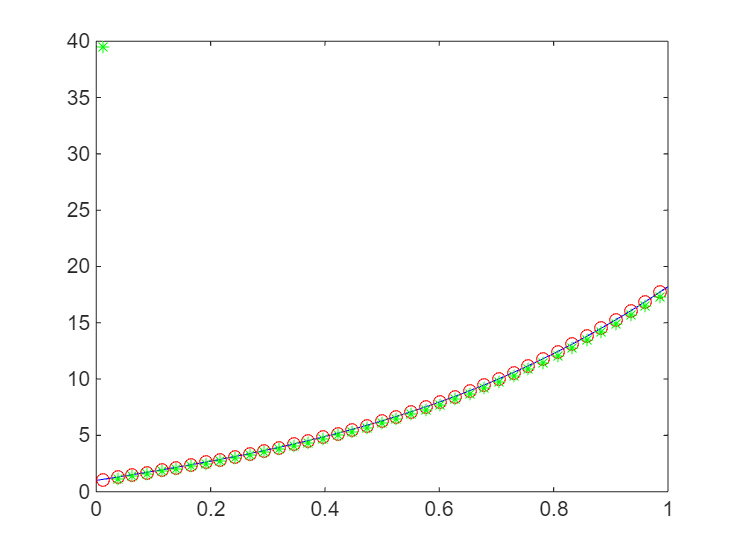

y_der = polyval(polyder(ppp),x);
xmean = (x(1:end-1) + x(2:end))/2;
plot(x,y_der,"b",xmean,D*y/h,"or",xmean(2:end),Dsym*y/h,"*g")

Теперь посмотрим на оператор второй производной:


$$\[
\frac{\partial^2 T}{\partial x^2}_{mn} \approx \frac{T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}}{\Delta x^2}
\]$$



$$\[
D^2 = \frac{1}{\Delta x^2}
[\matrix{
-2 & 1 & 0 & \cdots & 0 \cr
1 & -2 & 1 & \cdots & 0 \cr
0 & 1 & -2 & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & 1 \cr
0 & 0 & 0 & 1 & -2
}
]$$


Уравнение (1) может быть записано в матричной форме:


$$[\frac {1}{a(T)} ]D_t \cdot [T]  =[T]\cdot D_{xx}+   [\frac{\lambda'(T)}{\lambda(T)}]([T]\cdot D_x \circ [T] \cdot D_x)$$


$\circ$ - произведение Адамара (поэлементное умножение).

Предполагаем, что теплофизические свойства определяются по температурам в предыдущий момент времени. Построим сетку для координаты и времени:


$$x_n = n\Delta x, n\in 0...N$$
 


$$t_m = m\Delta t, m\in 0...M$$
 

Задача состоит в том, чтобы выразить через производную по времени распределение температуры по толщине образца в $m+1$-й момент времени, через распределение температуры в $m$ - й момент времени. 

Подставив выражения для производных в уравнение (1) получим:


$$\frac {1}{a_{mn}\Delta t} (T^{m+1}_n - T^{m}_n)  =\frac{1}{\Delta x^2} (T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1})+   \frac{1}{4\Delta x^2} \frac{\lambda'_{mn}}{\lambda_{mn}} (T^{m}_{n-1} - T^{m}_{n+1})^2 $$



$$ (T^{m+1}_n - T^{m}_n)  =F_{mn}(T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1})+   F_{mn}\frac{\lambda'_{mn}}{4\lambda_{mn}} (T^{m}_{n-1} - T^{m}_{n+1})^2 $$



$$F_{mn}=\frac{a_{mn}\Delta t}{\Delta x^2} $$


Выразим из этого уравнения температуру для следующего момента времени:


$$ T^{m+1}_n (1 + 2F_{mn})   - F_{mn}T^{m+1}_{n+1}  + F_{mn}T^{m+1}_{n-1}  =  T^{m}_n +   F_{mn}\frac{\lambda'_{mn}}{4\lambda_{mn}} (T^{m}_{n-1} - T^{m}_{n+1})^2 $$


Начальное условие:


$$T_n^0 = \phi(x_n)$$


Для учета граничных условий и расчета теплового потока, рекомендуется использовать разностные соотношения второго порядка точности, учитывающие накопление тепла на предыдущем шаге:

$q^{m+1}=\frac{\lambda_0^m}{\Delta x}(T_0^{m+1} - T_1^{m+1}) + C_0^m\frac{\Delta x}{2\Delta t}(T_0^{m+1} - T_0^m) $ - тепловой поток сверху

$\tilde q^{m+1}=\frac{\lambda_N^m}{\Delta x}(T_N^{m+1} - T_{N-1}^{m+1}) + C_0^m\frac{\Delta x}{2\Delta t}(T_N^{m+1} - T_N^m) $ - тепловой поток снизу

В матричной форме данные уравнения будут иметь вид:

FUNTIONS

function D = Dt(M)
% M- number of input matrix rows
    D = zeros(M-1,M);
    D(diagonal_inds(0,M-1,M)) = -1;
    D(diagonal_inds(1,M-1,M)) = 1;
end
function D = Dtsym(M)
% M- number of input matrix rows
    D = zeros(M-1,M);
    D(diagonal_inds(-1,M-1,M)) = -1/2;
    D(diagonal_inds(1,M-1,M)) = 1/2;
end
function D = D2t(N)
    D = zeros(N,N);
    D(diagonal_inds(0,M-1,M)) = -2;
    D(diagonal_inds(1,M-1,M)) = 1; 
    D(diagonal_inds(-1,M-1,M)) = 1;
end
function indices = diagonal_inds(diagonal_index,rows_number, columns_number)
    % diagonalIndicesRect returns linear indices of the k-th diagonal of an m x n matrix
    % m - number of rows
    % n - number of columns
    % k - diagonal number (0 = main, >0 above main, <0 below main)
    %
    % Linear indices are returned for the elements along the specified diagonal,
    % respecting matrix dimensions.
    
    if diagonal_index >= 0
        % Diagonal above or on main
        len = min(rows_number, columns_number-diagonal_index);
        rowIdx = 1:len;
        colIdx = (1:len) + diagonal_index;
    else
        % Diagonal below main
        len = min(rows_number+diagonal_index, columns_number);
        rowIdx = (1:len) - diagonal_index;
        colIdx = 1:len;
    end
    
    % Convert row and column indices to linear indices for column-major order
    indices = sub2ind([rows_number columns_number], rowIdx, colIdx);
end